# Интерполяция и Апроксимация

## Красницкий Никита

Интерполяция, как и апроксимация - метод получения промежуточных значений отчетов функции. Разница между ними в том, что для интерполирующей функции обязательно выполнение условия прохождения интерполирующей функции по узлам функции (выбраным опорным отчетам). А для апроксимирующей функции - основная задача заменить сложную и неизвестную функцию схожей более простой функцией. Апроксимирующая функция может не проходить через узлы, однако для апроксимации методом наименьших квадратов отклонений ошибка апроксимации может оказаться меньшей, чем в интерполирующей функции от чего апроксимация более известна.

clear all
close all
clc

Time = 4;           % Time of signals 2 sec
Fs   = 100;         % Sampling frequency 100Hz
dt   = 1/Fs;        % Time step
N    = Time/dt;     % Number of samples

t = 0:dt:Time-dt;   % Time reprosontation

Допустим есть функция (F), аналитический вид которой заранее неизвестен. К примеру это входной сигнал приемника или ВАХ неизвестного радиоэлемента. И известно только огранниченное кол-во отчетов функции (Ns). Вектор известных отчетов обозначу как S

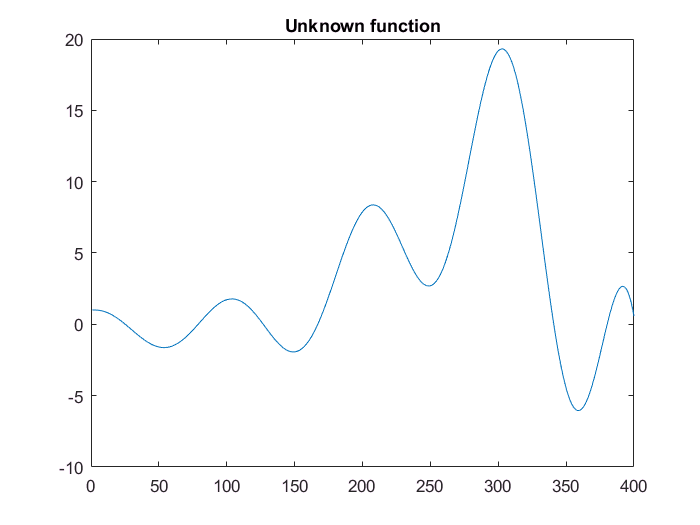

F = cos(2*pi*t).*2.^t - t.^2 + t.^4 - 0.25*t.^5;

figure
subplot(1,1,1);
plot(F);
title('Unknown function');

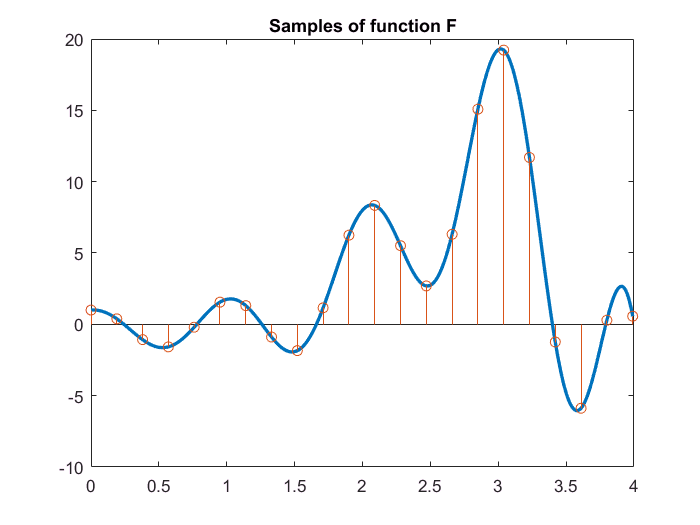


Ns  = 1:19:N;
dts = dt*19;
ts  = 0:dts:Time-dt;
S   = F(Ns);

figure
subplot(1,1,1);
plot(t, F, 'LineWidth', 2);                     
hold on                                         
stem(ts, S);  
hold off
title('Samples of function F');

Тривиальная интерполяция - линецная. Она получается путем соединения соседних отчетов пряміми отрезками.

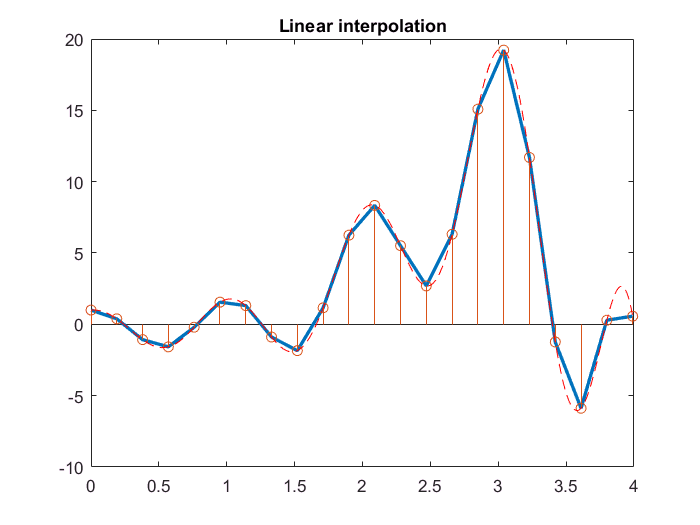

Xs = 1:N;
LinInter = interp1(ts, S, t, 'linear');

figure
subplot(1,1,1);
plot(t, LinInter, 'LineWidth', 2);
hold on                                         
stem(ts, S);  
plot(t, F, 'r--');
hold off
title('Linear interpolation');

Среднее квадратичное отклонение такой апроксимации (RMS)

DisperLin = sum((F(Xs) - LinInter(Xs)).^2) / N;
RmsLin = sqrt(DisperLin);
disp(['RMS for Linear Interpolation -> ', num2str(RmsLin)]);

RMS for Linear Interpolation -> 0.59935


Интерполяция полиномами может быть осуществела по МНК (методу наименьших квадратов). В таком случае для выбраного порядка полинома подбираются его коефициенты так, что бы интерполирующий полином минимально отклонялся от узлов, но не обязательно проходил между ними. Этот метод более подходящий для зашемленных сигналов, а так же он занимает меньше ресурсов для расчета, так как порядок полинома может быть ниже предыдущего примера.

p6     = polyfit(ts, S, 5 );
p12    = polyfit(ts, S, 12);

p22    = polyfit(ts, S, 21);

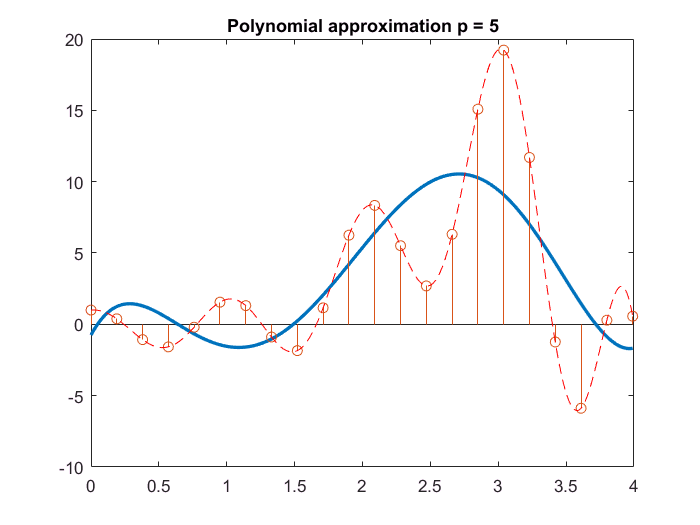

PolF5  = polyval(p6,t); 
PolF12 = polyval(p12,t); 
PolF22 = polyval(p22,t); 

figure
subplot(1,1,1);
plot(t, PolF5, 'LineWidth', 2);
hold on                                         
stem(ts, S);  
plot(t, F, 'r--');
hold off
title('Polynomial approximation p = 5');


DisperP5 = sum((F(Xs) - PolF5(Xs)).^2) / N;
RmsP5 = sqrt(DisperP5);
disp(['RMS for Polynomial approximation P5 -> ', num2str(RmsP5)]);

RMS for Polynomial approximation P5 -> 4.1406


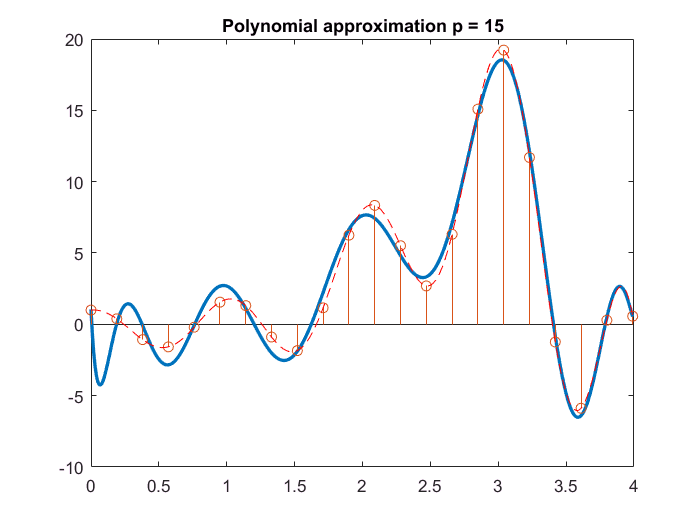


figure
subplot(1,1,1);
plot(t, PolF12, 'LineWidth', 2);
hold on                                         
stem(ts, S);  
plot(t, F, 'r--');
hold off
title('Polynomial approximation p = 15');


DisperP12 = sum((F(Xs) - PolF12(Xs)).^2) / N;
RmsP12 = sqrt(DisperP12);
disp(['RMS for Polynomial approximation P12 -> ', num2str(RmsP12)]);

RMS for Polynomial approximation P12 -> 1.072


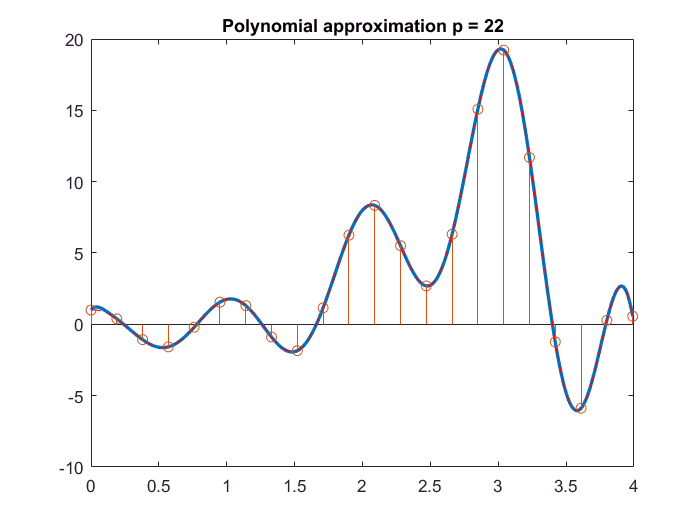


figure
subplot(1,1,1);
plot(t, PolF22, 'LineWidth', 2);
hold on                                         
stem(ts, S);  
plot(t, F, 'r--');
hold off
title('Polynomial approximation p = 22');


DisperP22 = sum((F(Xs) - PolF22(Xs)).^2) / N;
RmsP22 = sqrt(DisperP22);
disp(['RMS for Polynomial approximation (less-sqare) P22 -> ', num2str(RmsP22)]);

RMS for Polynomial approximation (less-sqare) P22 -> 0.031234


Интерполяция полиноминальным многочленом может иметь ввиду решение системы линейных однородных уравнений узлов (отчетов). Тогда кол-ву используемых узлов будет соответсвовать порядок полинома и интерполирующий полином точно будет проходить через узлы. 

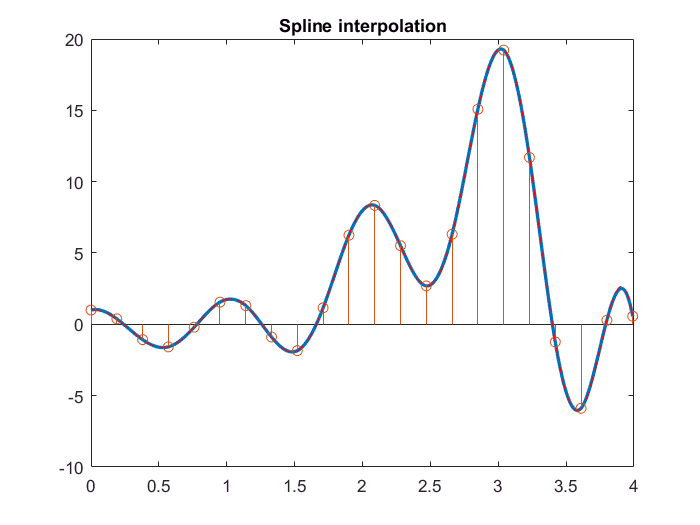

SplineInter = spline(ts, S, t);

figure
subplot(1,1,1);
plot(t, SplineInter, 'LineWidth', 2);
hold on                                         
stem(ts, S);  
plot(t, F, 'r--');
hold off
title('Spline interpolation');


DisperSpline = sum((F(Xs) - SplineInter(Xs)).^2) / N;
RmsSpline = sqrt(DisperSpline);
disp(['RMS for Spline Interpolation -> ', num2str(RmsSpline)]);

RMS for Spline Interpolation -> 0.033685


Интерполяция полиномами вносит изгибы, что может быть не желательным для апроксимации цифрового сигнала. На следующем примере сравним апроксимацию цифрового сигнала (Sd) для его отчетов (S) кубическими спайнами и сплайнами Акимы

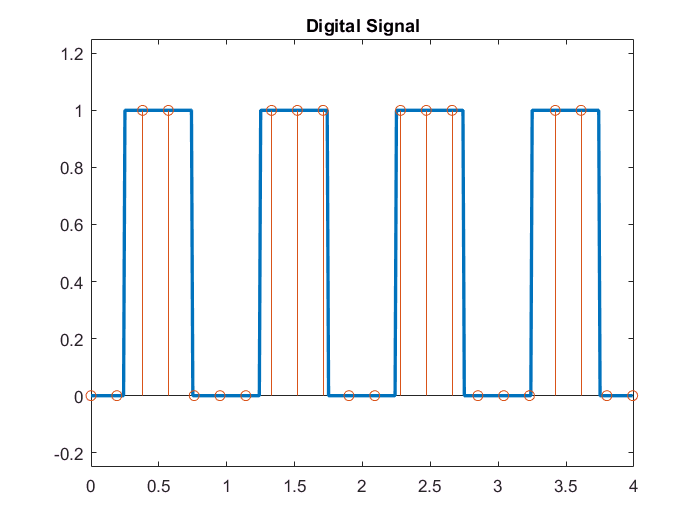

Sd                = zeros(1,N/16);    
Sd(N/16+1:N/8)     = ones(1, N/16);     
Sd(N/8 + 1: N/4)  = rot90(Sd);       
Sd                = repmat (Sd, 1, 4);  
Sd                = reshape(Sd, 1, N);  

S = Sd(Ns);

figure
subplot(1,1,1);
plot(t, Sd, 'LineWidth', 2);
hold on                                         
stem(ts, S);  
hold off
ylim([min(Sd)-0.25, max(Sd)+0.25])
title('Digital Signal');

Интерполяция кубическими сплайнами

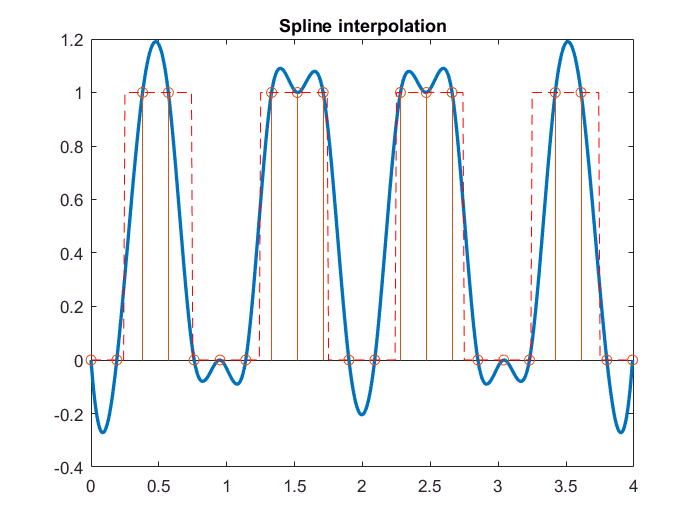

CubeSpline = spline(ts, S, t);

figure
subplot(1,1,1);
plot(t, CubeSpline, 'LineWidth', 2);
hold on                                         
stem(ts, S);  
plot(t, Sd, 'r--');
hold off
title('Spline interpolation');


DisperSpline = sum((Sd(Xs) - CubeSpline(Xs)).^2) / N;
RmsSpline = sqrt(DisperSpline);
disp(['RMS for Spline Interpolation -> ', num2str(RmsSpline)]);

RMS for Spline Interpolation -> 0.27097


Апроксимация кубическим полиномом

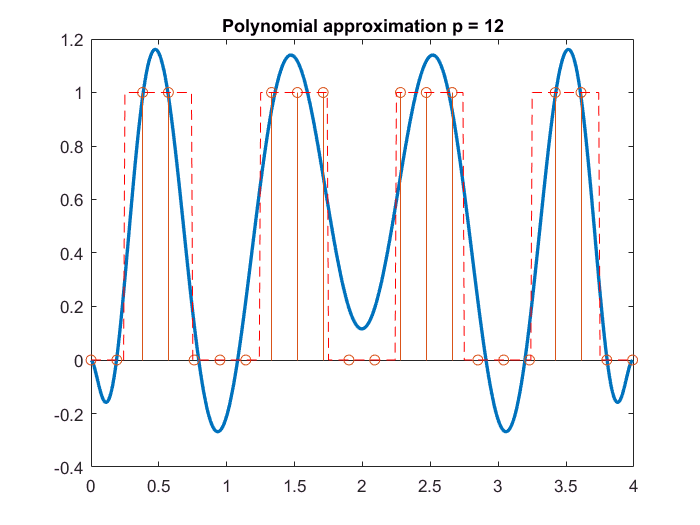

[p12,~,mu]    = polyfit(ts, S, 12); 
PolF12 = polyval(p12,t,[],mu); 

figure
subplot(1,1,1);
plot(t, PolF12, 'LineWidth', 2);
hold on                                         
stem(ts, S);  
plot(t, Sd, 'r--');
hold off
title('Polynomial approximation p = 12');


DisperP12 = sum((Sd(Xs) - PolF12(Xs)).^2) / N;
RmsP12 = sqrt(DisperP12);
disp(['RMS for Polynomial approximation P12 -> ', num2str(RmsP12)]);

RMS for Polynomial approximation P12 -> 0.26258


Апроксимация сплайнами Акимы. Хироши Акима предложил более устойчивые сплайны, у которых наблюдается меньше неожиданных выбрасов между отчетами, как в кубических сплайнах.

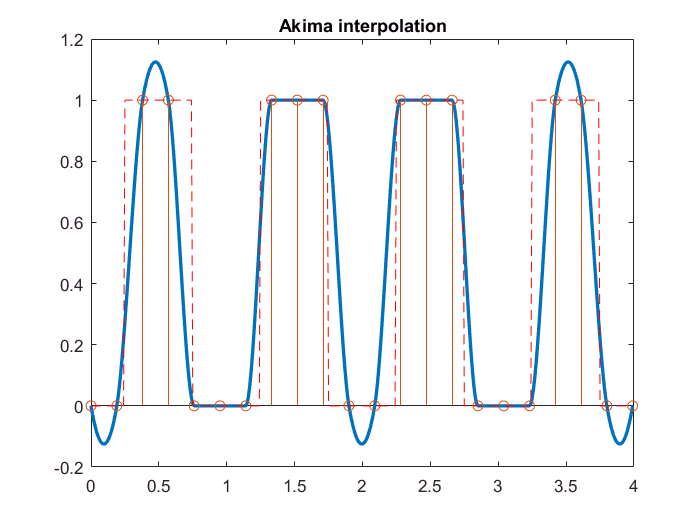

MakimaSpline = akimai(ts, S, t)';

figure
subplot(1,1,1);
plot(t, MakimaSpline, 'LineWidth', 2);
hold on                                         
stem(ts, S);  
plot(t, Sd, 'r--');
hold off
title('Akima interpolation');


DisperAkima = sum((Sd(Xs) - MakimaSpline(Xs)).^2) / N;
RmsAkima = sqrt(DisperAkima);
disp(['RMS for Akima inerpolation -> ', num2str(RmsAkima)]);

RMS for Akima inerpolation -> 0.26943
